startup_rvc;

Robotics, Vision & Control: (c) Peter Corke 1992-2011 http://www.petercorke.com
- Robotics Toolbox for Matlab (release 9.10)
 - pHRIWARE (release 1.1): pHRIWARE is Copyrighted by Bryan Moutrie (2013-2022) (c)
Run rtbdemo to explore the toolbox


L = [46 107 107 110]

L =     46   107   107   110


DHParams = [0 L(1) 0 sym(pi)/2;
            0 0 L(2) 0;
            0 0 L(3) 0;
            0 0 L(4) 0];            

Lnk(1) = Link(DHParams(1,:));
Lnk(2) = Link(DHParams(2,:));
Lnk(3) = Link(DHParams(3,:));
Lnk(4) = Link(DHParams(4,:));


R = SerialLink(Lnk,'name','PhantomX');

H_tool = [0 0 1 0;
          1 0 0 0;
          0 1 0 0;
          0 0 0 1];

R.tool = H_tool

 
R = 
 
PhantomX (4 axis, RRRR, stdDH, fastRNE)                          
                                                                 
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|         46|          0|       pi/2|          0|
|  2|         q2|          0|        107|          0|          0|
|  3|         q3|          0|        107|          0|          0|
|  4|         q4|          0|        110|          0|          0|
+---+-----------+-----------+-----------+-----------+-----------+
                                                                 
grav =    0  base = 1  0  0  0   tool =  0  0  1  0              
          0         0  1  0  0           1  0  0  0              
       9.81         0  0  1  0           0  1  0  0              
                    0  0  0  1           0  0  0  1              
 

syms q [1 4]
R.fkine(q)

$$ans = \begin{array}{l} \left(\begin{array}{cccc} -\sigma_{1}\,\cos\left(q_{1}\right) & \sin\left(q_{1}\right) & \sigma_{3}\,\cos\left(q_{1}\right) & \cos\left(q_{1}\right)\,\sigma_{2}\\ -\sigma_{1}\,\sin\left(q_{1}\right) & -\cos\left(q_{1}\right) & \sigma_{3}\,\sin\left(q_{1}\right) & \sin\left(q_{1}\right)\,\sigma_{2}\\ \sigma_{3} & 0 & \sigma_{1} & 110\,\sigma_{1}+107\,\sin\left(q_{2}+q_{3}\right)+107\,\sin\left(q_{2}\right)+46\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sin\left(q_{2}+q_{3}+q_{4}\right)\\ \sigma_{2}=110\,\sigma_{3}+107\,\cos\left(q_{2}+q_{3}\right)+107\,\cos\left(q_{2}\right)\\ \sigma_{3}=\cos\left(q_{2}+q_{3}+q_{4}\right) \end{array}$$

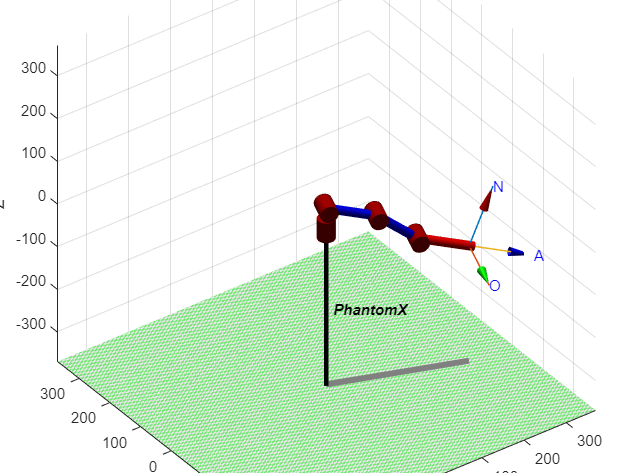


% figure
% R.plot([0 0 0 0],'noa')
figure
R.plot(pi/180*[-20 -20 -20 20],'noa')


% figure
% R.plot(pi/180*[30 -30 30 -30],'noa')
% 
% figure
% R.plot(pi/180*[-90 15 -55 17],'noa')
% 
% figure
% R.plot(pi/180*[-90 45 -55 45],'noa')

